# Compare full 3D camera motion with parallax estimate

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering

ieInit();
sceneLuminance = 200;
numRays = 32;
filmResolution = 64;
pbrtLensFile = true; 
sceneChoice = "Chess Set";
% apertureDiameter = 6;% in mm

% for legacy reasons, scenes don't have a uniform naming scheme,
% so we map the user's choice to the appropriate options
if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "Cornell Box Reference")
    scenePath = "cornell_box";
    sceneName = "cornell_box";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','dgauss.22deg.6.0mm.json');


Read 9 materials and 3 textures..


% add a skymap and a light
pbrtCPScene.thisR.set('skymap','room.exr','rotation val',[-90 180 0]);

lightName = 'from camera';
ourLight = piLightCreate(lightName,...
                        'type','distant',...
                        'cameracoordinate', true);

pbrtCPScene.thisR.set('light', ourLight,'add');


## Create our sample camera

Just one module with a pre-made sensor and default optics.

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorCreate('imx363'); 
ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Take Pictures using Auto, HDR, and Burst Intents

For the simplest case we ask our camera to take some pictures using pre-defined intents. By deault our camera assumes the 'Auto' intent. We also demonstrate 'Burst', which will capture more frames if the camera type we are using supports it. 'HDR' also fires a burst, but bracketed. Our default camera sums the frames in Burst mode, and chooses the highest non-saturated value at each pixel for HDR mode.

Elapsed time is 3.666422 seconds.
Started Docker (status 0): docker  --context remote-mux run -d -it  --gpus device=0  --name pbrt-gpu-Windows15856  -v /home/david/iset/iset3d-v4/local:/iset/iset3d-v4/local  digitalprodev/pbrt-v4-gpu-ampere-mux bash
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.18 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 35.14 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  0.97 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 41.7 sec ***

Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/is

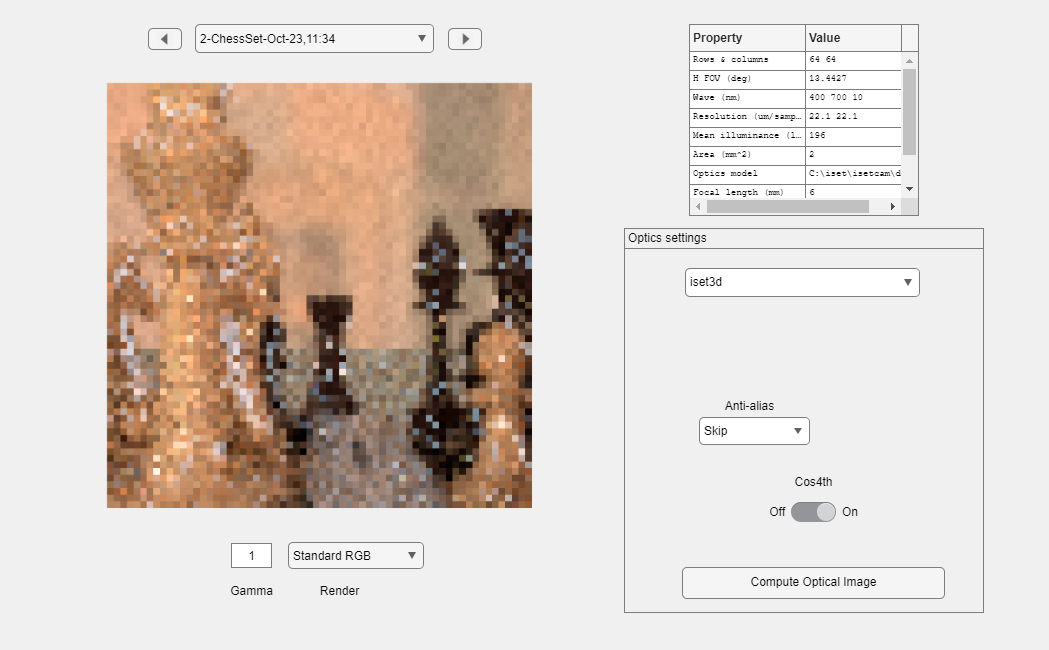

autoImage = ourCamera.TakePicture(pbrtCPScene, 'Auto',...
    'imageName','Auto Mode no motion', 'insensorIP',false); 

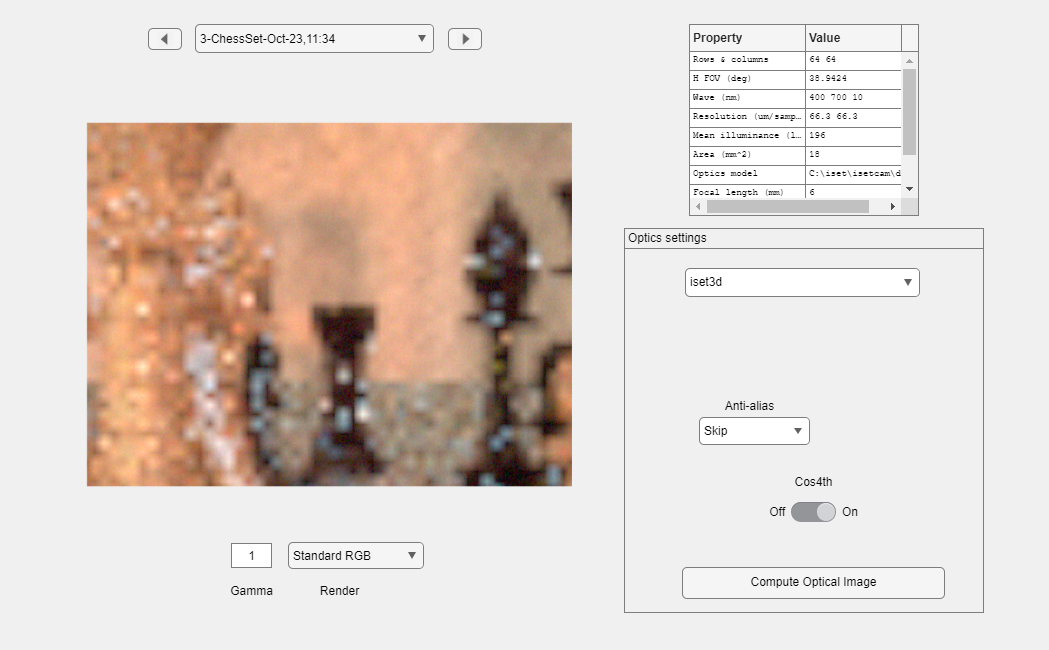

Elapsed time is 4.040982 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.18 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 6.34 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  0.96 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 9.5 sec ***



Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.07 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 2.91 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  0.96 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 6.1 sec ***

Elapsed time is 3.597042 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (0.97 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet

imshow(autoImage);

hdrSensorImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in sensor no motion', ...
    'insensorIP', true);

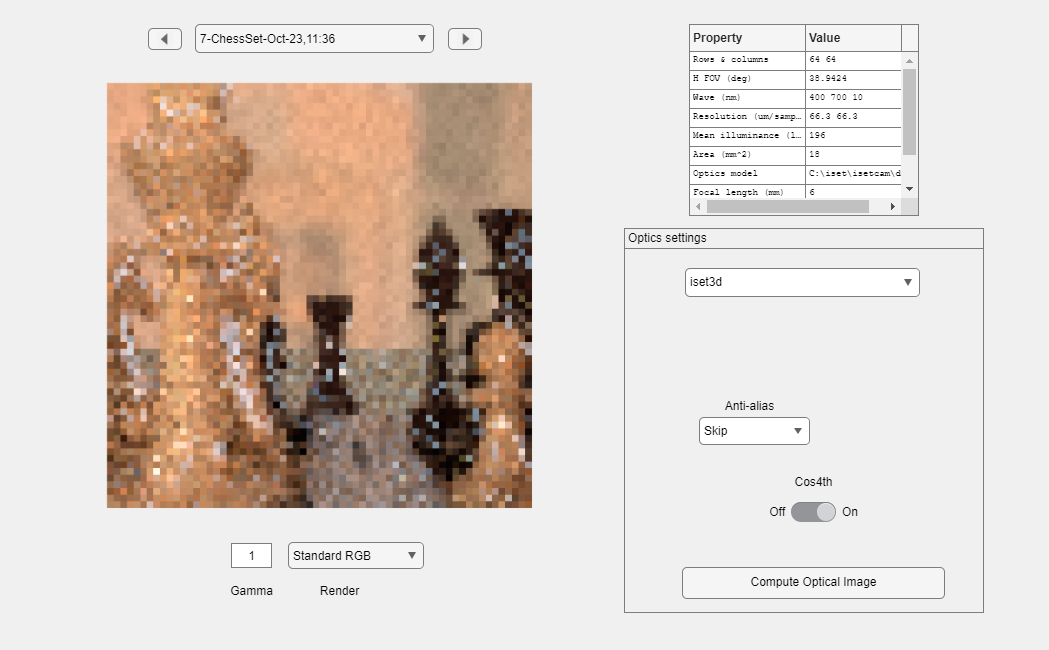

Elapsed time is 3.872375 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.27 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 6.25 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  1.07 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 9.7 sec ***



Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (0.96 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 2.89 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  1.06 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 5.9 sec ***

Elapsed time is 3.228690 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (0.96 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet

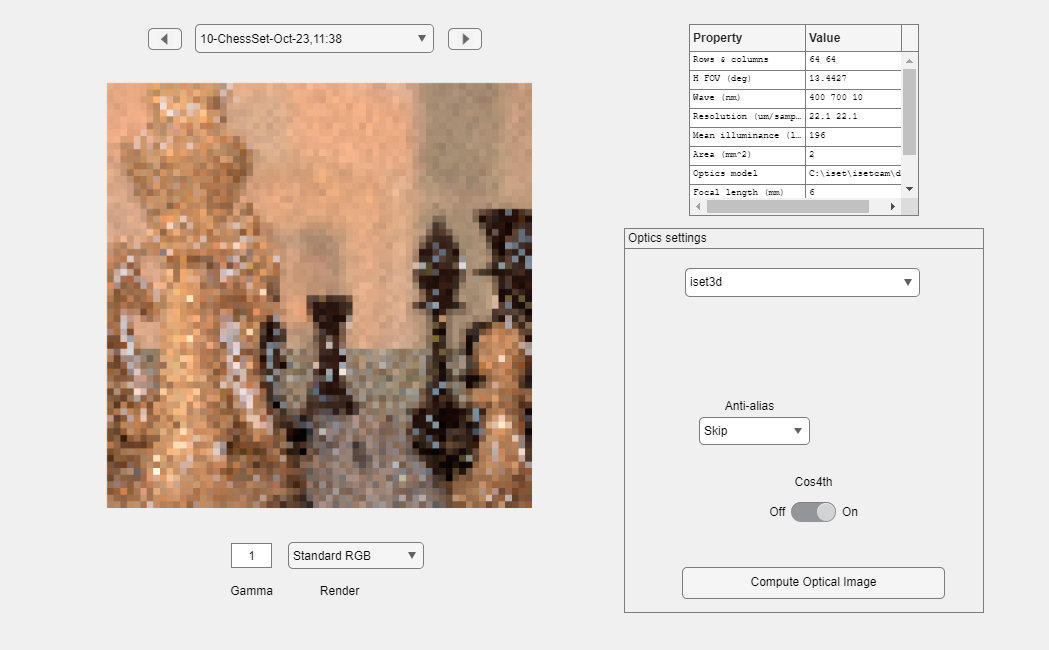


burstSensorImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in Sensor',...
    'insensorIP',true);

HDR vs Burst with no moion

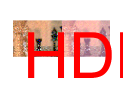

cpCompareImages(hdrSensorImage, burstSensorImage, 'HDR vs Burst with no moion');

## Now we add a small amount of camera motion

Combining multiple frames into a single image can either be done at the sensor level, or a higher-level in the ISP. At the sensor level the default strategies implemented by ISETCam are to sum the individual frames for Burst mode, and select the image with the most signal at each pixel for HDR. Once there is camera motion, though, those algorithms create errors in registration.

So our BurstCamera allows us to turn on Enhanced Processing, which does HDR by rendering each frame and then using image registration and tone-mapping to create the result. Both are "off-the-shelf" algorithms, so one place for experimentation and innovation is improving upon them, perhaps by using some of the papers from Google and others. For Burst, only image registration is used. This simple form of image registration relies on a single geometric transformation of the entire image, so it does not help with object motion.

pbrtCPScene.cameraMotion = {{'unused', [.002, 0, 0], [0, 0, 0]}}; % first tuple is translation, second is rotation

hdrMotionImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in ISP with Motion', ...
    'insensorIP', true);

Elapsed time is 3.123540 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (0.97 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 6.10 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  1.56 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 9.7 sec ***

Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.02 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet

In sensor HDR without and with motion

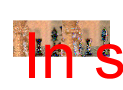

cpCompareImages(hdrSensorImage, hdrMotionImage, 'In sensor HDR without and with motion');

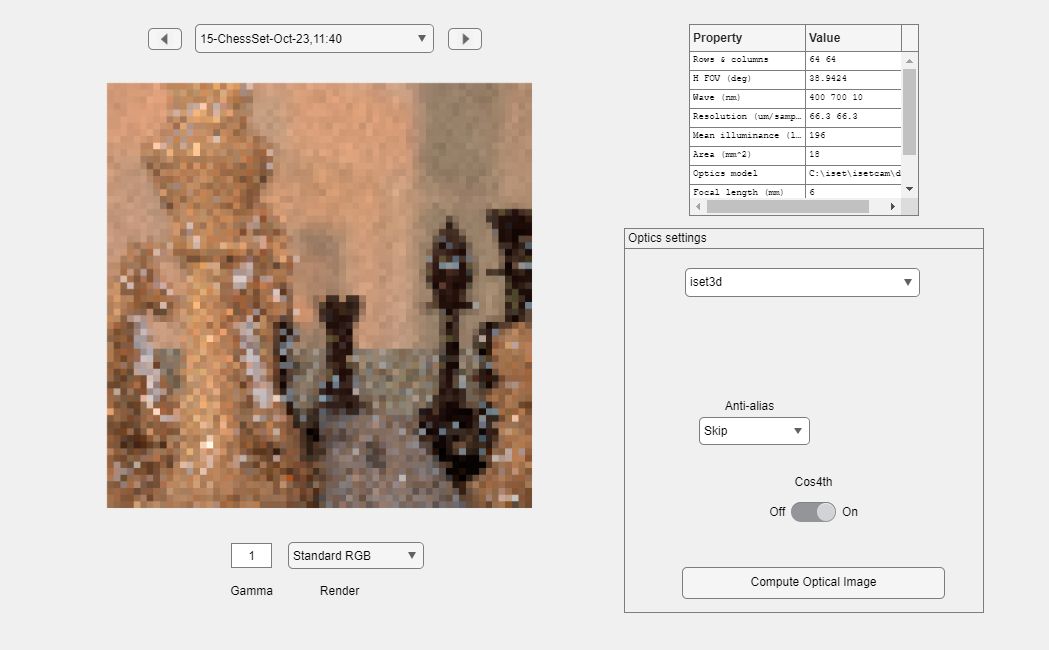

Elapsed time is 3.474604 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (0.97 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 5.90 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  1.07 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 8.9 sec ***



Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.05 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 2.79 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  0.96 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 5.9 sec ***

Elapsed time is 3.790918 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.42 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet


% Now try with firmware ISP ("Enhanced Processing" setting)
hdrISPMotionImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in ISP with Motion', ...
    'insensorIP', false);

Tonemap vs. In sensor HDR in Camera Motion Case

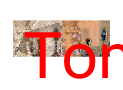

cpCompareImages(hdrISPMotionImage, hdrMotionImage, 'Tonemap vs. In sensor HDR in Camera Motion Case');

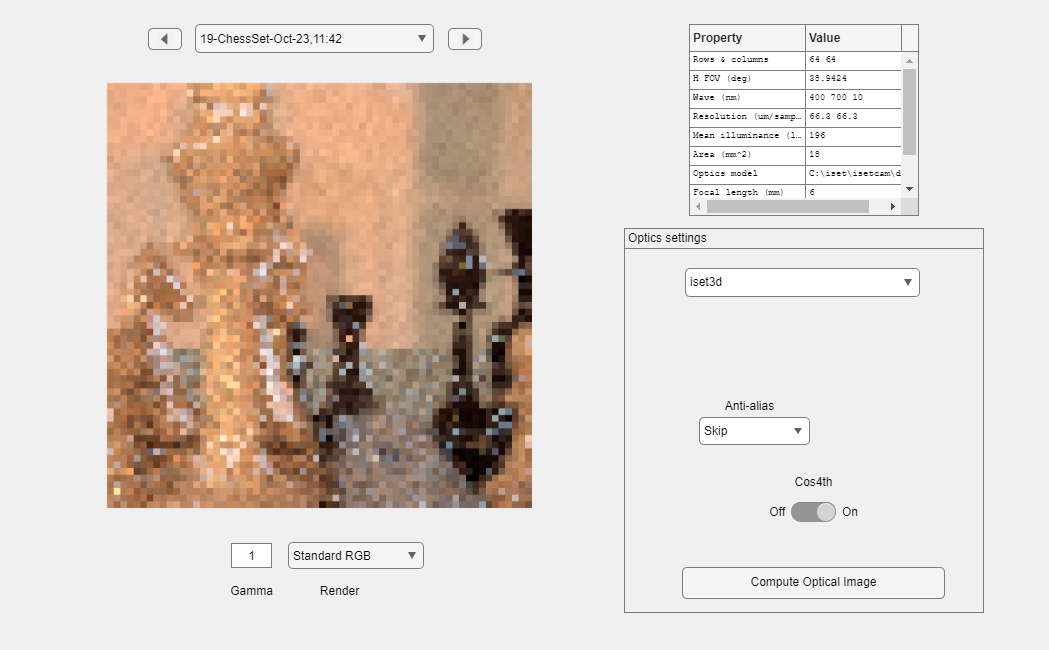

Elapsed time is 3.831697 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.08 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 6.23 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  1.29 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 9.7 sec ***



Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.08 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 2.91 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  0.96 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 6.0 sec ***

Elapsed time is 3.775250 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (0.98 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows15856 sh -c "cd /iset/iset3d-v4/local/ChessSet

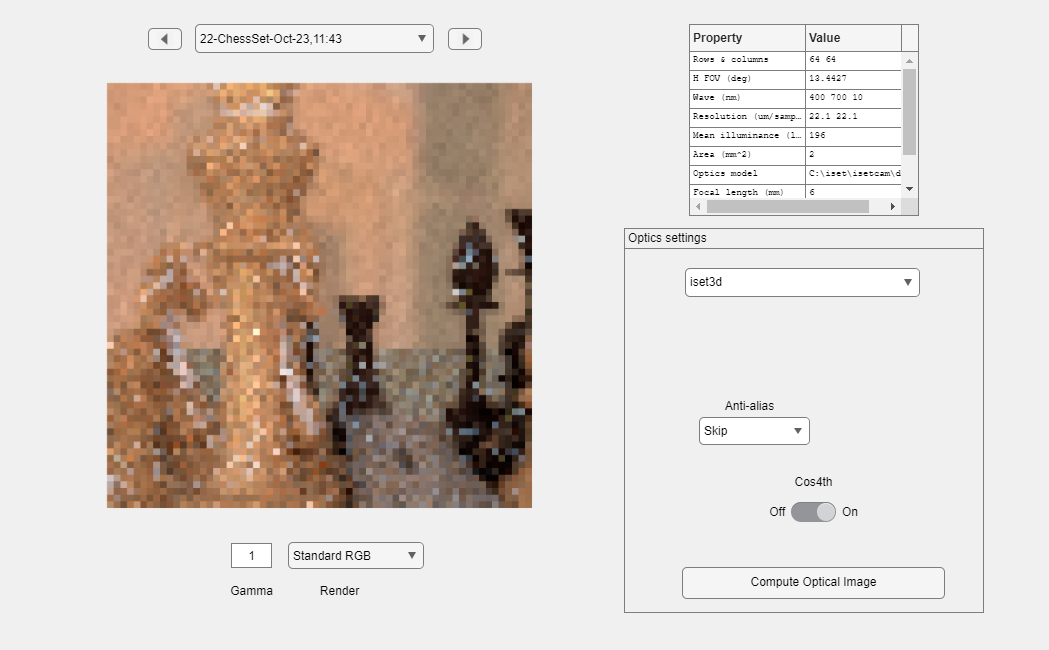


burstMotionImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in ISP with Motion',...
    'insensorIP',false);

HDR vs. Burst in ISP for Camera Motion Case

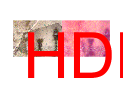


cpCompareImages(hdrISPMotionImage, burstMotionImage,"HDR vs. Burst in ISP for Camera Motion Case");

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCompare ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 

cpCompare ran  on: Intel Intel(R) Iris(R) Xe Graphicswith driver version: 4.5.0 - Build 31.0.101.3675


disp(strcat("cpCompare ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));

cpCompare ran  in: 1284.2188 seconds of CPU time.


disp(strcat("cpCompare ran  in: ", string(tTotal), " total seconds."));

cpCompare ran  in: 675.1829 total seconds.
